clc,clear  

## Main

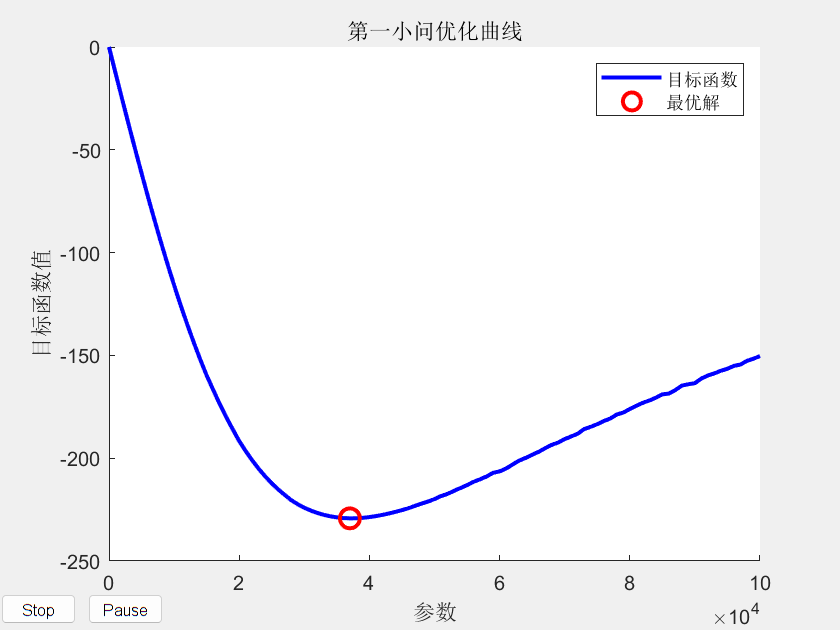

x_ub= 100000;
% 定义参数范围和步长
param_range = 0:1000:x_ub;

% 计算目标函数值
objective_values = zeros(size(param_range));
for i = 1:length(param_range)
    objective_values(i) = Obj_fun(param_range(i));
end
% 绘制曲线
plot(param_range, objective_values, 'b-', 'LineWidth', 2);
hold on;
[best_value, best_index] = min(objective_values);
best_param = param_range(best_index);
plot(best_param, best_value, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
title('第一小问优化曲线');
xlabel('参数');
ylabel('目标函数值');
legend('目标函数', '最优解');

narvs = 1;
x_lb = 3e+4;
x_ub = 4.5e+4; % x的上界

%options = optimoptions('particleswarm','HybridFcn',@fmincon);
options = optimoptions('particleswarm','PlotFcn','pswplotbestf','Display','iter')   

options =   particleswarm 选项:

   设置属性:
                   Display: 'iter'
                   PlotFcn: 'pswplotbestf'

   默认属性:
               CreationFcn: @pswcreationuniform
         FunctionTolerance: 1.0000e-06
                 HybridFcn: []
              InertiaRange: [0.1000 1.1000]
        InitialSwarmMatrix: []
          InitialSwarmSpan: 2000
             MaxIterations: '200*numberofvariables'
        MaxStallIterations: 20
              MaxStallTime: Inf
                   MaxTime: Inf
      MinNeighborsFraction: 0.2500
            ObjectiveLimit: -Inf
                 OutputFcn: []
      SelfAdjustmentWeight: 1.4900
    SocialAdjustmentWeight: 1.4900
                 SwarmSize: 'min(100,10*numberofvariables)'
               UseParallel: 0
             UseVectorized: 0



                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              10          -229.1          -227.6        0
    1              20          -229.2          -228.3        0
    2              30          -229.3            -228        0
    3              40          -229.3          -228.4        1
    4              50          -229.3          -228.3        2
    5              60          -229.3          -228.3        3
    6              70          -229.3          -228.1        4
    7              80          -229.3          -227.6        0
    8              90          -229.3          -228.3        1
    9             100          -229.3          -227.7        0
   10             110          -229.3          -227.9        1
   11             120          -229.3          -227.9        2
   12             130          -229.3            -228        3
   13             140          -229.3          -

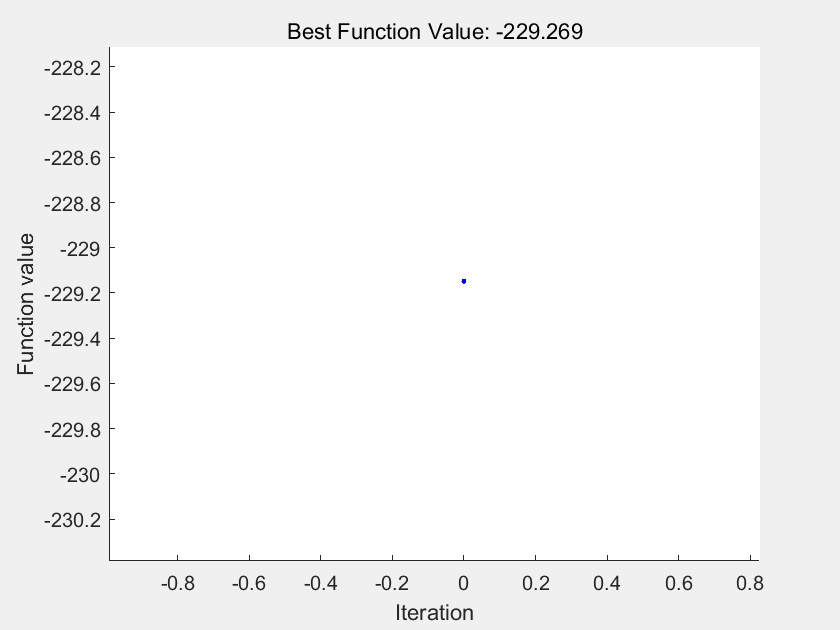

x = 3.7425e+04

fval = -229.2689

exitflag = 1

output = 包含以下字段的 struct :
      rngstate: [1×1 struct]
    iterations: 28
     funccount: 290
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'
    hybridflag: []


[x,fval,exitflag,output] = particleswarm(@Obj_fun, narvs, x_lb, x_ub,options) 

fprintf('最大平均功率为%f',fval)

最大平均功率为-229.268852

function [W]=Obj_fun(c)
    %initialize parameter
    g=9.8;                                   %重力加速度 (m/s2)                               
    %%初值设置               
    v1=0;                                    %浮子的初始速度 (m/s)
    v2=0;                                    %振子的初始速度 (m/s)
    x_f=0;                                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
    x_v=0;                                   %振子的初始位移 (m)
    X0=[x_f;x_v;v1;v2];
    w=2.2143;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）
    T=2*pi/w;
    T_end=floor(80*T);                              %总数值模拟时间(s) 
    tspan=[0,T_end];   
    options = odeset('MaxStep', 0.1);        % 设置最大步长为 0.1
    [t, X] = ode45(@(t,X)S_diff_equ(t,X,c), tspan, X0, options);
    X=X';
    delta_v=X(3,:)-X(4,:);
    l=length(t);
    W=trapz(t(l-floor(l/10):end),c*delta_v(l-floor(l/10):end).^2)/(t(end)-t(l-floor(l/10)));
    W=-W;
end
% function delta_f=ca_f_float(rho,g,x,V0,V_max,r_cost,h) 
%     if x<=-h
%         delta_V=V0-V_max;
%     elseif x<=3-h&&x>-h
%         delta_V=-x*h*pi*r_cost^2; 
%     elseif x<=3.8-h&&x>3-h
%         delta_V=-pi*r_cost^2*(3-h)-1/3*pi*((3.8-x)/0.8)^2*(3.8-x);
%     else 
%         delta_V=-V0;
%     end
%     delta_f=rho*g*delta_V;
% end
function dxdt=S_diff_equ(t,X,k) 
    %initialize parameter
    m1=4866;                                 %浮子质量 (kg)
    r_f=1;                                   %浮子底半径 (m)
    h_cast=3;                                %浮子圆柱部分高度 (m)
    h_cone=0.8;                              %浮子圆锥部分高度 (m)
    V_cast=pi*r_f^2*h_cast;                  %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2;              %圆锥体积(m3)
    V_max=V_cone+V_cast;                     %浮子体积
    m2=2433;                                 %振子质量 (kg)
    m_add=1165.992;                          %垂荡附加质量 (kg)
    g=9.8;                                   %重力加速度 (m/s2)
    G1=m1*g;                                 %浮子重力  (N)
    G2=m2*g;                                 %振子重力  (N)
    rho=1025;                                %海水的密度 (kg/m3)
    ke=80000;                                %弹簧刚度 (N/m)
    w=2.2143;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr=167.8395;                             %垂荡兴波阻尼系数 (N·s/m)
    f_max=4890;                              %垂荡激励力振幅 (N)
    V0=V_max-(G1+G2-f_max)/(rho*g);          %初始沉入水中体积(m3)
    r_cost=1;                                %浮子底半径 (m)
    h=(V_max-(m1*g+m2*g)/(rho*g))/pi;        %水面的高度(m)
    dxdt=zeros(4,1);
    dxdt(1)=X(3);
    dxdt(2)=X(4);
    dxdt(3)=(-k*(X(3)-X(4))-ke*(X(1)-X(2))+f_max*cos(w*t)-kr*X(3)-rho*g*pi*r_cost^2*X(1))/(m1+m_add);
    dxdt(4)=(k*(X(3)-X(4))+ke*(X(1)-X(2)))/m2;   
end
